# Prey-Predator population.

Do not edit. This code solves for the predator and prey populations for 3 weeks, with 10 prey and 2 predators initially.

tRange = [0 20];
Y0 = [10;2];
[tSol,YSol] = ode45(@odefun,tRange,Y0);

## Task 1

The first column of the solution matrix `YSol` represents x, the prey population.

Task

Extract the column vector that represents the **prey** population from the solution matrix `YSol` and assign it to the variable `x`.

x=YSol(:,1)

x =    10.0000
    9.9927
    9.9702
    9.9321
    9.8776
    9.5003
    8.8660
    8.0106
    7.0064
    5.9526


## Task 2

The second column of the solution matrix `YSol` represents y, the predator population.

Task

Extract the column vector that represents the **predator** population from the solution matrix `YSol` and assign it to the variable `y`.

y=YSol(:,2)

y =     2.0000
    2.1030
    2.2111
    2.3242
    2.4423
    2.9510
    3.5136
    4.0954
    4.6509
    5.1282


## Task 3

Plot the prey population `x` as a function of `tSol`.

plot(tSol,x)

### Task 4

Add a plot of the predator population to the figure.

Remember to use the `hold` `on` and `hold` `off` commands.

hold on
plot(tSol,y)
hold off


## Task 5

There are two lines on your plot. The first represents the prey population, and the second represents the predator population. 

Add a descriptive legend to your plot using the `legend` function.

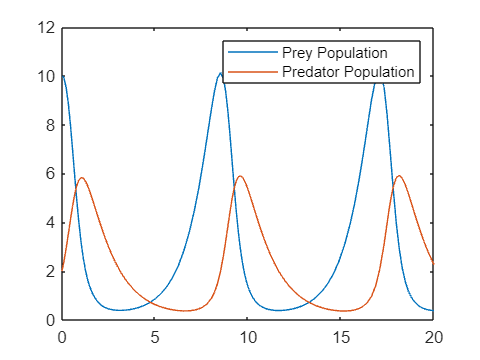

legend("Prey Population","Predator Population")

## Task 6

Use the `max` function to determine the maximum **predator** population and assign this value to the variable `ymax`.

You may want to leave off the semicolon to display the result.

ymax=max(y)

ymax = 5.9228

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

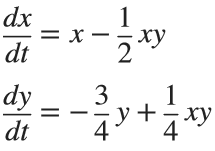

function dYdt = odefun(t,Y)
x = Y(1); % prey
y = Y(2); % predator
dxdt = x - 1/2*x*y;
dydt = -3/4*y + 1/4*x*y;
dYdt = [dxdt;dydt];
end